# Simulating Trajectory Noise

Objective: This script will show you how the process noise affects a robot's trajectory and why dead reackoning is not an accurate solution for robot localization. 

Helper Functions used in this exercise:

- *plotTraj *plots the map, the true trajectory, and the noisy trajectory

Execise:

This script will simulate a trajectory with process noise to show how this uncertainty affects the movement of the robot.

Complete the code below to

- Define the control maxtrix for the simulated trajectory:  Travel east with speed of 1 m/s for 2 seconds, then travel west with a speed of 0.5 m/s for 2 seconds. Create the control matrix, u with the x and y velocity components over 4 second long trajectory. 

- Define the kinematic equations for a holonomic robot $x_{t+1} = Ax_t + B u_t$. 

- Define the Matrix R is the covariance matrix for the process noise

- Generate a true trajectory by looping through the control inputs u and applying the kinematic updates for each time step. Using the true trajectory, add noise to each timestep to create a noisy trajectory. 

% ---- Initialization---- 
%Load map
map = load('MAP102.txt'); %TO DO: NEED TO LOAD THIS MAP FROM RELATIVE PATH (AA doesn't know how to do this)

%Define robot starting location (just x,y) and the time step
robotXY = [-1.5; -.5];
dt = 0.05;

**COMPLETE THE CODE BELOW**

%1. Define simulated trajectory

time = 2; %Insert your code here
%N = Number of timesteps for time
N = round(time/dt); %Insert your code here
Vx = [ones(1,N), -0.5*ones(1,N)]; %Insert your code here
Vy = [zeros(1,N), zeros(1,N)]; % %Insert your code here
% u = control matrix
u = [Vx; Vy];  %Insert your code here

%2. Define Kinematic equation
A = [1,0;0,1];
B = [dt,0;0,dt];

%3. Define the process noise
R = [.14 0; 0 .14]; %Insert your code here

% 4. Create the true trajectory and the noisy trajectory 
%Initialize trajectory vector
robotXYtraj = zeros(2,1+length(u)); %Insert your code here
robotXYtrajNoisy = zeros(2,1+length(u)); %Insert your code here

%Loop through control inputs to create trajectory
%CODE BLOCK BELOW IS NOT PROVIDED IN STARTER CODE
robotXYtraj(:,1) = robotXY; 
robotXYtrajNoisy(:,1) = robotXY;
for i = 1:length(u)
    robotXYtraj(:,i+1) = A*robotXYtraj(:,i) + B*u(:,i); % Kinematics without noise
    robotXYtrajNoisy(:,i+1) = A*robotXYtrajNoisy(:,i) + B*u(:,i) +  ...
                              dt.*sqrt(R)*randn(2,1); % Kinematics with noise
end

Plot the resulting noisy trajectory versus the non-noisy one. 

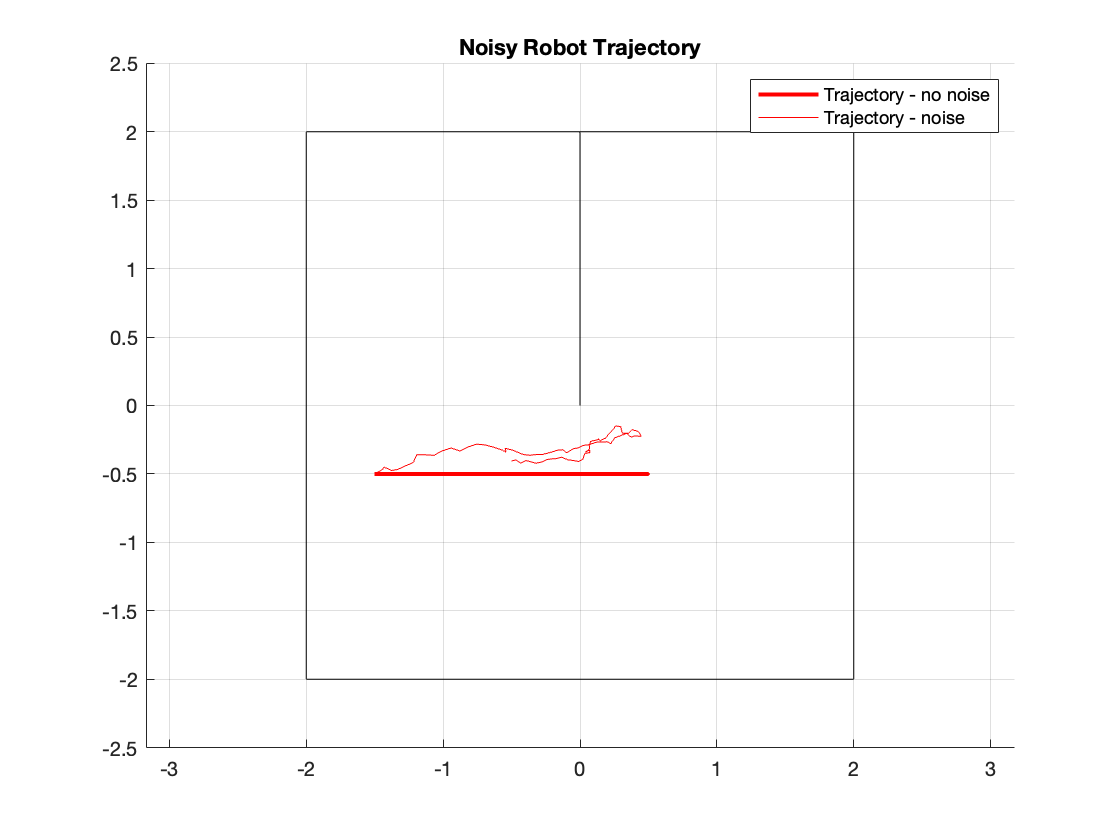

plotTraj(map, robotXYtraj, robotXYtrajNoisy); 

Expected Results: The plot should depict 2 different trajectories, one true trajectory (that looks like a perfect line) and a more realistic trajectory with noise. 

Check your Comprehension: Do your results make sense? Compare the noisy trajectory with the true trajectory. Adjust the variance process noise.What do you notice about the trajectory as you change the variance?